# Accessing Two-Photon Calcium Imaging Data from the Allen Brain Observatory

This tutorial demonstrates access and basic analysis of the Visual Coding 2P dataset [1] from the Allen Brain Observatory [2] using the [Brain Observatory Toolbox](https://github.com/emeyers/Brain-Observatory-Toolbox) (BOT). This public dataset consists of 2-photon calcium imaging ("ophys") experiments from a range of cortical areas and depths. 

The Brain Observatory Toolbox consists of functions and classes, contained within its top-level [package folder](https://www.mathworks.com/help/matlab/matlab_oop/scoping-classes-with-packages.html) +bot, which are referenced from MATLAB with the prefix `bot`.

### About the Brain Observatory Toolbox (BOT)

The BOT is a MATLAB toolbox for conveniently accessing, manipulating and analysing neurophysiology data from the Allen Brain Observatory. The BOT consists of functions and classes, contained within its top-level [package folder](https://www.mathworks.com/help/matlab/matlab_oop/scoping-classes-with-packages.html) +bot, which are referenced from MATLAB with the prefix `bot`.

### The Visual Coding 2P Dataset

The Visual Coding 2P dataset contains optical electrophysiology data obtained using in-vivo two-photon calcium imaging. Targeted expression, using Cre-lines, of the fluorescent calcium sensor GCaMP6 in 6 different cortical areas and 4 cortical layers was used [3]. Intrinsic imaging in anesthetized mice was used to automatically define the boundaries of the visual cortical areas using response characteristics [4].  A dataset comprises 3 imaging sessions (~90 mins each) at a given location (cortical area and depth). Each dataset contained the following data types, each recorded with a sampling rate of 30 Hz:

- 2p movies (512 x 512 pixels) 

- eye tracking data

- behavior (running speed)

The data is described by several tables containing metadata whereas the actual data is stored in NWB files. Running this demo require data to be downloaded and may take some time the first time. However, the data is then cached by this toolbox making subsequent runs faster. Metadata stored in tables is used to pre-select the data required for an analysis following which, only the minimum required actual data from the NWB files is accessed.

### Accessing Visual Coding 2P Dataset Items

The 2P data is grouped and organized into experimental `sessions` as shown in the schematic below. Experiment containers include experimental `sessions` with the same targeted imaging area, depth and Cre line but different stimulus protocols.

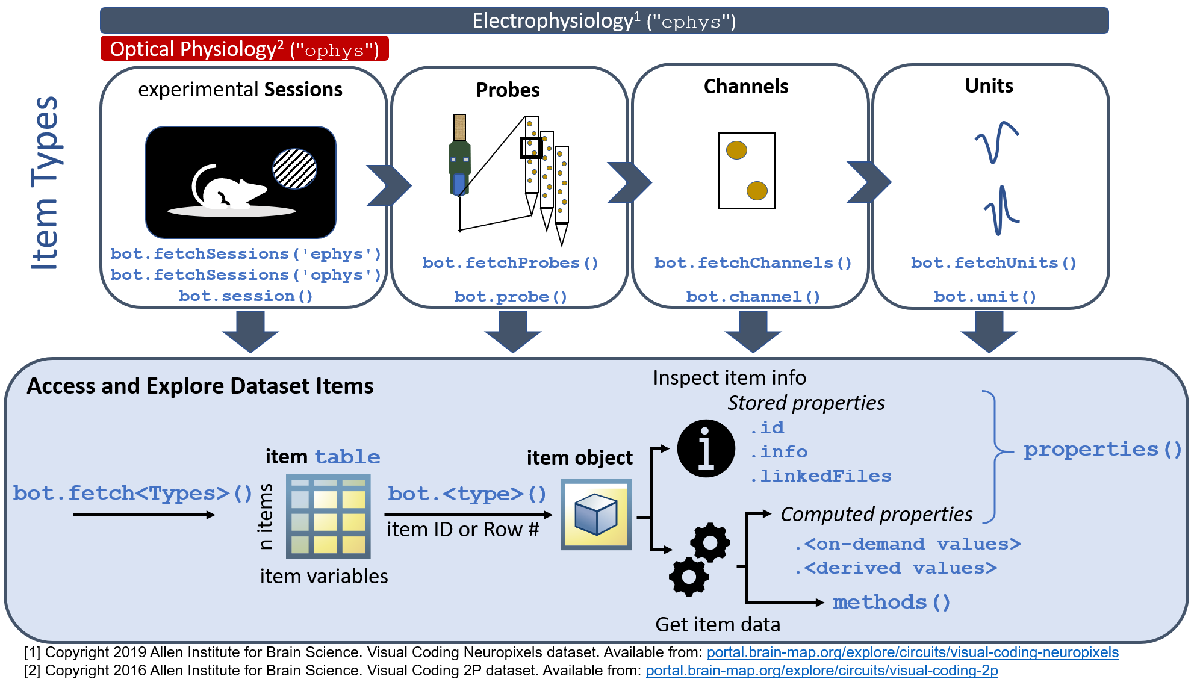

To access the sessions, first use the fetch function of the form `bot.fetchSessions('ophys'). `This retrieves tables of the available experimental *sessions *with session parameters such as unique identifiers (`id`) . An individual `session` can be queried from the table (using the row) or as an object (using the session id). Objects come with properties used to inspect information related to that particular session or methods for fetching or analyzing data linked to that particular session.

For example,` bot.session(session_id)` retrieves a single experimental session.

availSessions = bot.fetchSessions('ophys');

Inspecting the size of thise table array with the command `whos` reveals the dataset is quite extensive:

whos availSessions 

  Name                  Size               Bytes  Class    Attributes

  availSessions      2684x14            68745981  table              



This dataset content table consists of rows of dataset items (`sessions`) whose column-oriented variables contain individual session information. Since tables are inherently two-dimensional, their size can also be expressed by their height (number of rows) and width (number of columns). Here the command `height` returns the number of sessions: 

disp("There are " + height(availSessions) + " available sessions in the Visual Coding 2P dataset")

There are 2684 available sessions in the Visual Coding 2P dataset


The Visual Coding 2P dataset consists of thousands of experimental sessions.

### Examining Sessions

Each ophys session is one continuous recording session [5].

#### Inspecting Available Sessions 

The `head` command can be used to inspect a table's structure via its first few rows. Let's inspect the available experimental sessions:

head(availSessions)

ans = 8×14 table
       id        experiment_container_id     stimulus_name     targeted_structure_acronym    fail_eye_tracking    imaging_depth        cre_line        date_of_acquisition                     name                     specimen_id    experiment_container      specimen      targeted_structure    well_known_files
    _________    _______________________    _______________    __________________________    _________________    _____________    ________________    ____________________    _____________________________________    ___________    ____________________

Session information is returned as a table. Columns correspond to session parameters, and the table variables provide information for each session, such as the imaging depth and the targeted visual area brain structure. Casting such values into `categorical` variables makes it easy to show a summary of the counts for each unique value:

% show a summary of the sessions by imaging depth
summary(categorical(availSessions.imaging_depth));

     51         1 
     65         1 
     67         2 
     69         5 
     71        11 
     73        12 
     75        88 
     77         8 
     79        15 
     81         9 
     83         7 
     85         3 
     87         2 
     91         1 
     93         1 
     95         1 
     132        1 
     140        2 
     142        2 
     144        6 
     145        2 
     146        3 
     147        1 
     148        7 
     149        2 
     150       85 
     152       12 
     154   

The majority of sessions were collected at imaging depths of 175, 275, 350, and 375$\mu$m. Several (39) sessions were also collected deeper into the cortical column at 550$\mu$m.

% show a summary of the sessions by targeted structure
summary(categorical(availSessions.targeted_structure_acronym));

     VISal       138 
     VISam       120 
     VISl        715 
     VISp       1306 
     VISpm       282 
     VISrl       123 


#### Selecting Sessions of Interest

Table [indexing operations](https://www.mathworks.com/help/matlab/matlab_prog/access-data-in-a-table.html) can be used to select specific experimental sessions (rows) with attributes of interest (column values). For instance, by combining [dot notation with logical indexing](https://www.mathworks.com/help/matlab/matlab_prog/access-data-in-a-table.html#mw_77d04ebd-b6f7-4ee9-93ac-1cc1fd7bc735), we can extract ("filter") sessions where the anterolateral (AL), rostrolateral (RL), and anteromedial (AM) areas of the primary visual cortex (V1) were imaged in specific Cre lines (Cux2-CreERT2) at a cortical depth of 175 µm with accompanying eye tracking data during specific stimulus presentations.

% select experiments from the most orientation/direction-selective areas of visual cortex 
filteredSessions = availSessions(ismember(availSessions.targeted_structure_acronym, categorical(["VISal" "VISrl" "VISam"])), :);

% select experiments with GCaMP6f expression enriched in Layer 2/3 and Layer 4 of cortex
filteredSessions = filteredSessions(filteredSessions.cre_line == "Cux2-CreERT2", :);

% select experiments imaging from the shallowest depth in Layer 2/3
filteredSessions = filteredSessions(filteredSessions.imaging_depth == 175,:);

% select experiments with eye tracking data available
filteredSessions = filteredSessions(~filteredSessions.fail_eye_tracking, :);

% select experiments with drifting grating and natural movie stimuli
filteredSessions = filteredSessions(filteredSessions.stimulus_name == "three_session_A", :);

Only a few sessions remain:

disp("Only " + height(filteredSessions) + " experimental sessions are now available")

Only 10 experimental sessions are now available


#### Creating Session Objects 

The Brain Observatory Toolbox defines [classes](https://www.mathworks.com/help/matlab/matlab_oop/classes-in-the-matlab-language.html) to represent individual Visual Coding 2P dataset items as [objects](https://www.mathworks.com/help/matlab/matlab_oop/classes-in-the-matlab-language.html). These objects can be inspected and worked with via their defined [properties and methods](https://www.mathworks.com/help/matlab/matlab_oop/classes-in-the-matlab-language.html).

A set of top-level functions (`bot.session`, `bot.probe`, `bot.channel`, `bot.unit)` are provided to create object arrays for dataset items of the corresponding content type. In the BOT, all experimental data are represented by summaries, with loading of large data files (slow) performed only when necessary. 

For example, the `bot.session` function can be called to create an object representing the first session item in the `filteredSessions` table above by supplying an ID. These factory functions also can be supplied with a table array, whose rows will be converted to object array elements. For instance, easily create an object for the first session in `filteredSessions` via table indexing:

sessionUnderStudy = bot.session(filteredSessions(1,:)); 

This is a lightweight object; no experimental data has been downloaded, but we can examine some of the parameters of the session by accessing the object property `info`, which provides a [structure](https://www.mathworks.com/help/matlab/ref/struct.html) (field-wise) representation of the values from the table row.

sessionUnderStudy.info

ans = struct with fields:
                            id: 503412730
       experiment_container_id: 511510695
                 stimulus_name: three_session_A
    targeted_structure_acronym: VISal
             fail_eye_tracking: 0
                 imaging_depth: 175
                      cre_line: "Cux2-CreERT2"
           date_of_acquisition: 23-Feb-2016 19:10:20
                          name: "20160223_222425_3StimA"
                   specimen_id: 495727000
          experiment_container: [1×1 struct]
                      specimen: [1×1 struct]
            targeted_structure: [1×1 struct]
              well_known_files: [3×1 struct]


#### Inspecting Session Object Properties

Display the `sessionUnderStudy` object to see its full set of properties, which can provide further access into its underlying data. Scroll through the displayed output to inspect the full set:

disp(sessionUnderStudy)

  OphysSession with properties:

                                   info: [1×1 struct]
                                     id: 503412730
                           session_type: three_session_A
                            linkedFiles: [2×1 table]

   Linked File Values ('SessNWB')
                      cell_specimen_ids: '[on demand]'
          corrected_fluorescence_traces: '[on demand]'
                fluorescence_timestamps: '[on demand]'
                    fluorescence_traces: '[on demand]'
            fluorescence_traces_demixed: '[on demand]'
                fluorescence_traces_dff: '[on demand]'
                         max_projection: '[on demand]'
                      motion_correction: '[on demand]'
                             neuropil_r: '[on demand]'
                        neuropil_traces: '[on demand]'
                           nwb_metadata: '[on demand]'
                         

**Linked File Values**

*Linked File Values* properties represent direct and computed data values from the underlying data file(s) for the session (nicknamed "`SessNWB"`) and would require these data files to be downloaded or loaded from the cache. Since the Allen Brain Observatory data files, which are in Neurodata without Borders neurophysiology (NWB:N) format [[7]](https://www.biorxiv.org/content/10.1101/523035v1), can be quite large (sometimes in the GB range), the download is deferred ("on demand") until the property is accessed. Note that the first-time download is time-consuming.

These values are accessed via `.<LinkedFileValues>`, such as `.fluorescence_traces_dff`.

### Neuron Responses via Calcium Imaging Fluorescence Signals

Now, let's extract the fluorescence traces from the cells imaged in this session using the `.fluorescence_traces_dff` property. This causes the session data to be downloaded from the Allen Brain Observatory, which takes longer to complete.

The `.fluorescence_traces_dff` property contains a `[TxN]` matrix of fluorescence responses for each of the `N` neurons at each of the `T` `fluorescence_timestamps`:

timestamps = sessionUnderStudy.fluorescence_timestamps

timestamps = 115744×1 duration array
   9.9738 sec
   10.007 sec
    10.04 sec
   10.073 sec
   10.106 sec
    10.14 sec
   10.173 sec
   10.206 sec
   10.239 sec
   10.272 sec
   10.305 sec
   10.339 sec
   10.372 sec
   10.405 sec
   10.438 sec
   10.471 sec
   10.504 sec
   10.538 sec
   10.571 sec
   10.604 sec
   10.637 sec
    10.67 sec
   10.704 sec
   10.737 sec
    10.77 sec
   10.803 sec
   10.836 sec
   10.869 sec
   10.903 sec
   10.936 sec


traces = sessionUnderStudy.fluorescence_traces_dff;
whos traces

  Name             Size                Bytes  Class     Attributes

  traces      115744x119            55094144  single              



Now that we have the data for this session, let's plot a selection of the traces:

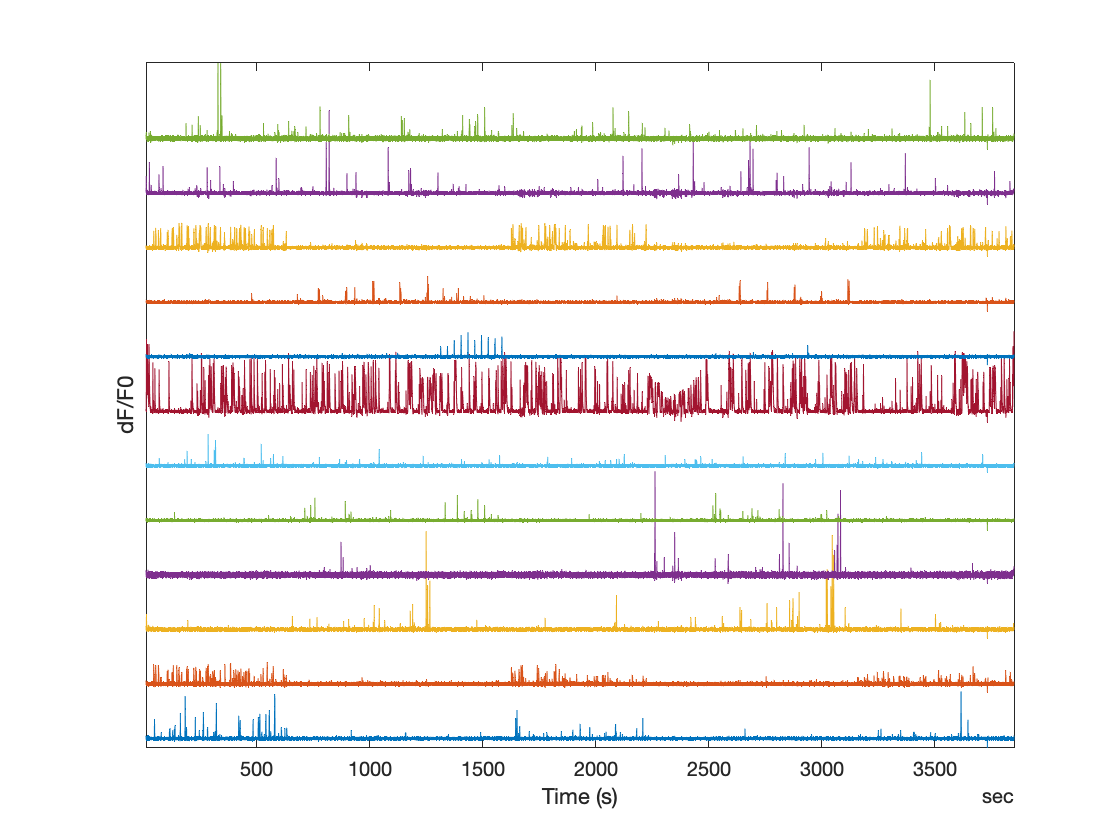

figure;
plot(timestamps, traces(:, 1:10:end) + (1:10:size(traces, 2))/3)
axis tight; xlabel('Time (s)'); set(gca, 'YTick', []); ylabel('dF/F0');

### Conclusion

This tutorial provides information about the methods and object properties in the BOT and explanations on their usage. For applications of these methods and properties in conducting analyses, see the ophys demo.

### References

[1] Copyright 2016 Allen Institute for Brain Science. Visual Coding 2P dataset. Available from: [http://portal.brain-map.org/explore/circuits/visual-coding-2p](http://portal.brain-map.org/explore/circuits/visual-coding-2p).

[2] Copyright 2016 Allen Institute for Brain Science. Allen Brain Observatory. Available from: [portal.brain-map.org/explore/circuits](http://portal.brain-map.org/explore/circuits). 

[3] Copyright 2016 Allen Institute for Brain Science. Visual Coding 2P dataset. Available from: [portal.brain-map.org/explore/circuits/visual-coding-2p](https://portal.brain-map.org/explore/circuits/visual-coding-2p).

[4] Visual Coding - 2P dataset documentation. Available from: [http://help.brain-map.org/display/observatory/Documentation.](http://help.brain-map.org/display/observatory/Documentation.)

[5] Visual Coding - 2P dataset documentation. Available from: [https://allensdk.readthedocs.io/en/latest/_static/examples/nb/visual_behavior_ophys_dataset_manifest.html](https://allensdk.readthedocs.io/en/latest/_static/examples/nb/visual_behavior_ophys_dataset_manifest.html).